# Dark/Light Days

Questions for Eric... Once normalized, can I combine channel 1 with channel 2?

clear day1
%set up
ReFs = 10;
idx = fivehouridx1

idx =     19    58    59




%day averages by trial and by sample day
    %channel 1
     for j = 1:length(idx)
          [day1(j).trial, day1(j).day] = KatieDayTrialDessembler(kg(idx(j)), 1, 48, ReFs);
     end
  
[pk(2).timforpi, pk(2).meanoftrialmeans, pk(2).ld] = k_daydessembledplotter(day1);
     

%set up
ReFs = 10;
idx = twelvehouridx2


    %channel 2
     for j = 1:length(idx)
          [day1(j).trial, day1(j).day] = KatieDayTrialDessembler(kg(idx(j)), 1, 48, ReFs);
     end
     


## 4:4 

pk(1) = channel 1

%channel 1 data
fourhouridx1 = [1 2 54];


%channel 2
fourhouridx2 = [1 2 55];

## 5:5

%channel 1 data
fivehouridx1 = [19 58 59];
%channel 2 data
fivehouridx2 = [19 96 59];

## 6:6

%channel 1 data
%34 is too short for 48 hour trial
sixhouridx1 = [8 32 33];
%channel 2 data
sixhouridx2 = [32 33];

## 8:8

%channel 1 data
eighthouridx1 = [27 25 26 35 36];
%channel 2 data
eighthouridx2 = [25 26 35 36];

## 10:10

%channel 1 data
tenhouridx1 = [6 7];
%channel 2 data
tenhouridx2 = [6 7];

## 12:12

%channel 1 data
twelvehouridx1 = [12 14 15 16];
%channel 2 data
twelvehouridx2 = [12 14 15 16 47];

## 13:13

%channel 1 data
thirteenhouridx1 = [31 28 29 30];
%channel 2 data
thirteenhouridx2 = [28 31 29 30];

## 16:16

%channel 1 data
sixteenhouridx1 = [41 42];
%channel 2 data
sixteenhouridx2 = [41 42];

## 20:20

%channel 1 data
twentyhouridx1 = [37 38 39 40];
%channel 2 data
twentyhouridx2 = [37 38 39 40];

## 24:24

%channel 1 data
twentyfourhouridx1 = [56 10 11];
%channel 2 data
twentyfourhouridx2 = [57 10 11];

## 48:48

%channel 1 data
fortyeighthouridx1 = [3 4 5 44 46 49];
%channel 2 data
fortyeighthouridx2 = [3 4 5 44 45 46 49];

## plot to check

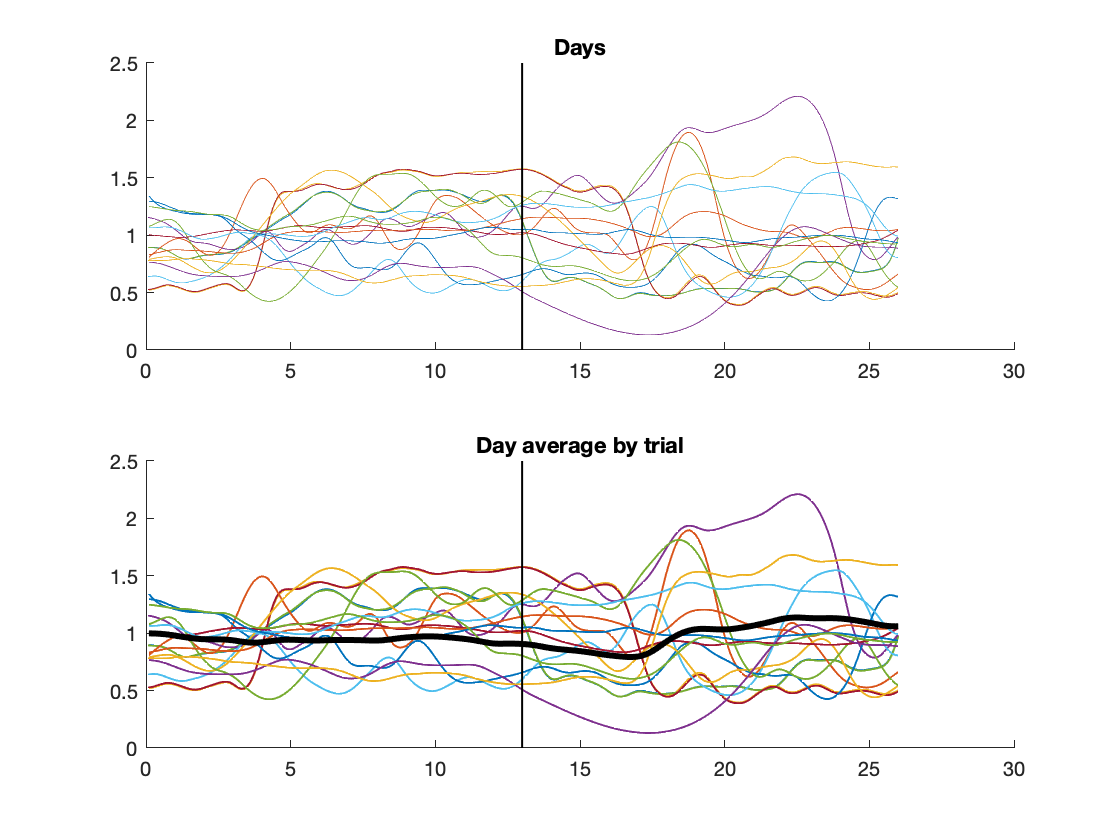


%see k_daysessembledplotter.m

 %all days
 %average day by trial
 figure(27); clf; hold on; title('Day average by trial');
 
 for j = 1:length(day14)
    for jj=1:length(day14(j).trial) 

        %create temporary vector to calculate mean by trial
        %t(j).mday(jj,:) = zeros(1,length(day14(j).trial(jj).tim));
        mday(jj,:) = zeros(1,length(day14(j).trial(jj).tim));
       % t(j).mmday(jj,:) = zeros(1,length(day14(j).trial(jj).tim));

        for k=1:length(day14(j).trial(jj).day)

                %fill temporary vector with data from each day 
                mday(jj,:) = mday(jj,:) + day14(j).trial(jj).day(k).SobwAmp;
               % t(j).mmday(jj,:) = t(j).mmday(jj,:) + day14(j).trial(jj).day(k).SobwAmp;
                
                %plot
                subplot(211); hold on; title('Days');
                plot(day14(j).trial(jj).tim, day14(j).trial(jj).day(k).SobwAmp);
                plot([ld ld], ylim, 'k-', 'LineWidth', 1);

        end

         % To get average across days, divide by number of days
            mday(jj,:) = mday(jj,:) / length(day14(j).trial(jj).day);
            %t(j).mmday(jj,:) = t(j).mmday(jj,:)/ length(day14(j).trial(jj).day);
            
            
            %plot
            subplot(212); hold on; title('Day average by trial');
            plot(day14(j).trial(jj).tim, mday(jj,:), '-', 'Linewidth', 1);
            plot([ld ld], ylim, 'k-', 'LineWidth', 1);

    end

   end    
    % Mean of means
 
    subplot(212); hold on;
     meanoftrialmeans = mean(mday); % Takes the mean of the means for a day from each trial 
    % mamamean = t(j).mmday / length(day14);
     %avgofmeans = mean(meanofmeans);
    plot(day14(1).trial(1).tim, meanoftrialmeans, 'k-', 'LineWidth', 3);

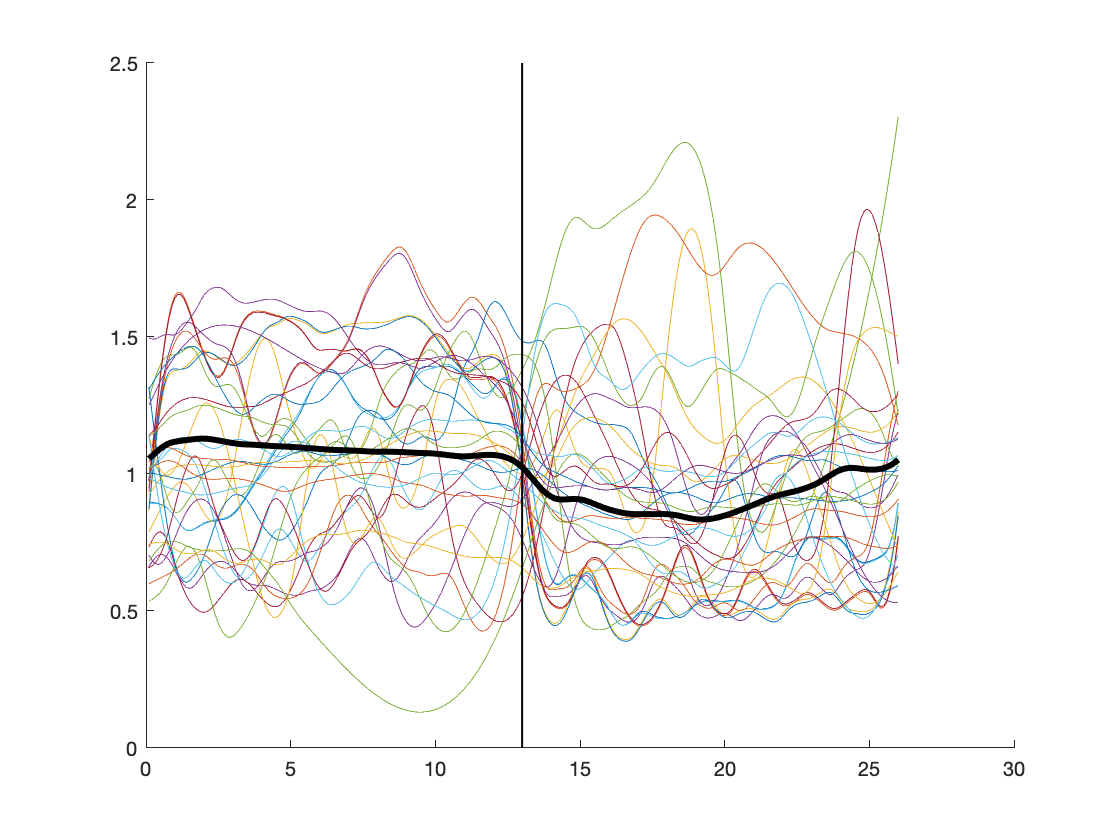

    %plot(day14(1).trial(1).tim, mamamean, 'm-','LineWidth', 3);
  

    
    
figure(28); clf; hold on; 

for j = 1:length(day14)

 for k = 1:length(day14(j).day)
        plot(day14(j).day(k).tim, day14(j).day(k).SobwAmp);
        td(j).meanday(k,:) = day14(j).day(k).SobwAmp;
 end
end
        mmday= mean(td(j).meanday);
        plot(day14(1).day(1).tim, mmday, 'k-', 'LineWidth', 3);
        plot([ld ld], ylim, 'k-', 'LineWidth', 1);

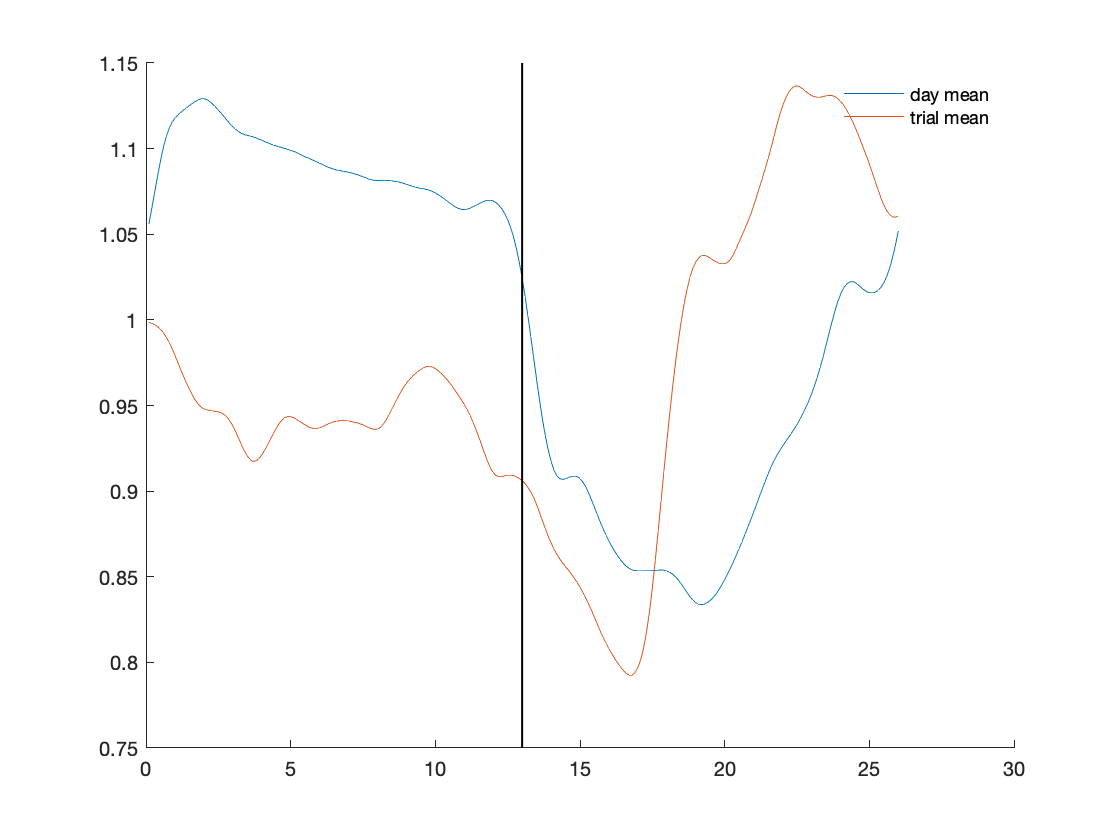

        
figure(29); clf; hold on;
    plot(day14(1).day(1).tim, mmday);
    plot(day14(1).trial(1).tim, meanoftrialmeans);
    plot([ld ld], ylim, 'k-', 'LineWidth', 1);
    legend('day mean', 'trial mean');
     legend('boxoff')